emg    = readtable('C:/Users/dante/OneDrive/Documentos/UDEM/PEF/PEF - IMT 2da prueba/PEF_IMT210.csv');         % Contains: EMG2, EMG3, EMG4, EMG5


dataEMG = emg{8:end,3:6}

dataEMG = 1.0e-03 *

   -0.0143   -0.0130   -0.0055   -0.0030
   -0.0135   -0.0120   -0.0049   -0.0040
   -0.0120   -0.0117   -0.0048   -0.0049
   -0.0114   -0.0121   -0.0048   -0.0038
   -0.0128   -0.0127   -0.0043   -0.0019
   -0.0128   -0.0115   -0.0044   -0.0016
   -0.0112   -0.0089   -0.0051   -0.0022
   -0.0110   -0.0086   -0.0044   -0.0028
   -0.0119   -0.0103   -0.0035   -0.0022
   -0.0133   -0.0108   -0.0035   -0.0022
   -0.0138   -0.0113   -0.0042   -0.0022
   -0.0124   -0.0117   -0.0042   -0.0021
   -0.0118   -0.0124   -0.0046   -0.0017
   -0.0122   -0.0124   -0.0055   -0.0023
   -0.0129   -0.0122   -0.0054   -0.0034


Fs = 2000;              % Sampling rate Hz

validRows = all(isfinite(dataEMG), 2);
dataEMG = dataEMG(validRows, :);

dataEMG1 = dataEMG(:,1);
dataEMG2 = dataEMG(:,2);
dataEMG3 = dataEMG(:,3);
dataEMG4 = dataEMG(:,4);

dataEMG = [dataEMG(:,1),dataEMG(:,2),dataEMG(:,3),dataEMG(:,4)];

N  = height(dataEMG);       % Number of EMG samples

t_emg = (0:N-1)' / Fs;  % EMG time vector (in seconds)


% --- Sampling settings ---

% --- Rectify (absolute value) ---
rectified = abs(dataEMG);

% --- Low-pass filter (to get EMG envelope) ---
fc_env = 5; % Hz, envelope cutoff (try 5, 10, 20 Hz for different smoothness)
[b, a] = butter(4, fc_env/(Fs/2), 'low');
filtered_signals = filtfilt(b, a, rectified);

% --- Integrated EMG (area under rectified curve) ---
iEMG = trapz(filtered_signals) / Fs;

disp('iEMG for each channel:');

iEMG for each channel:


disp(iEMG);

    0.0012    0.0010    0.0005    0.0002



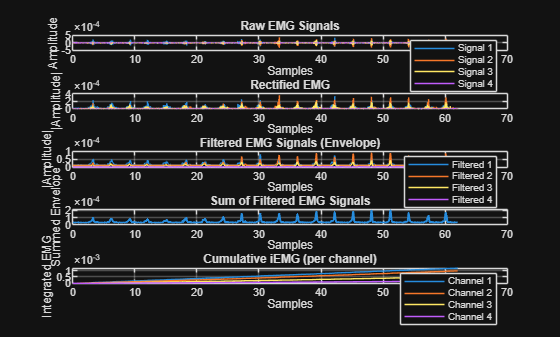


% --- Compute sum of signals (optional normalization if desired) ---
sum_signal = sum(filtered_signals, 2);  % sum across channels
% sum_signal = sum(filtered_signals, 2) / size(filtered_signals, 2); % mean instead of sum

% --- Plot ---
figure;

subplot(5,1,1);
plot(t_emg,dataEMG);
title('Raw EMG Signals');
xlabel('Samples'); ylabel('Amplitude');
legend('Signal 1','Signal 2','Signal 3','Signal 4');
grid on;

subplot(5,1,2);
plot(t_emg,rectified);
title('Rectified EMG');
xlabel('Samples'); ylabel('|Amplitude|');
grid on;

subplot(5,1,3);
plot(t_emg,filtered_signals);
title('Filtered EMG Signals (Envelope)');
xlabel('Samples'); ylabel('|Amplitude|');
legend('Filtered 1','Filtered 2','Filtered 3','Filtered 4');
grid on;

subplot(5,1,4);
plot(t_emg,sum_signal, 'LineWidth', 1.5);
title('Sum of Filtered EMG Signals');
xlabel('Samples'); ylabel('Summed Envelope');
grid on;

cumulative = cumsum(filtered_signals)/Fs;
subplot(5,1,5);
plot(t_emg,cumulative);
title('Cumulative iEMG (per channel)');
xlabel('Samples'); ylabel('Integrated EMG');
legend('Channel 1','Channel 2','Channel 3','Channel 4');
grid on;


% Final cumulative iEMG
disp('Final cumulative iEMG:');

Final cumulative iEMG:


disp(sum(cumulative(end,:)));

    0.0028

